# Time Response Analysis for an Electric Heater

### System Identification Experiment

Using PROTEUS simulation and interactive analysis with no control over the heater (connected directly to the power source, or duty cycle = 100%), the connection diagram is as shown below:

### 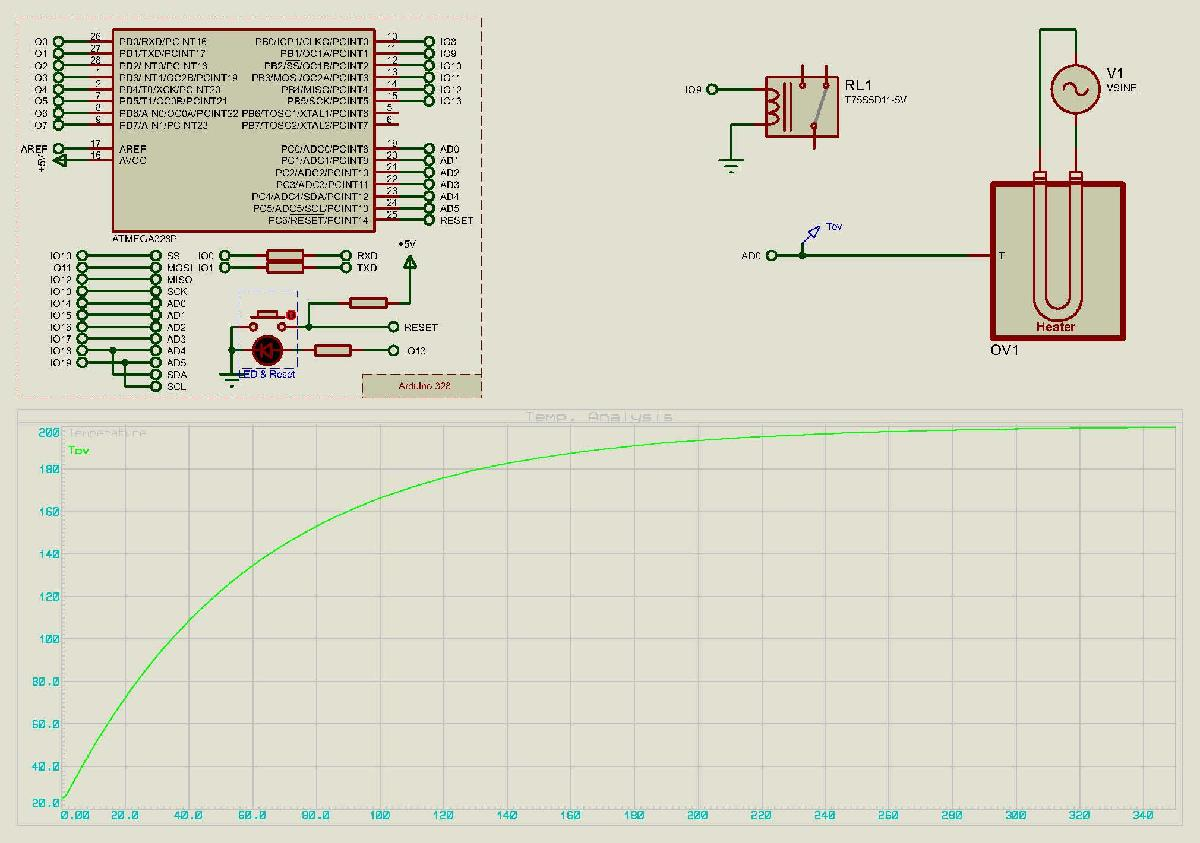

#### Heater parameters

The heater parameters were specified as follows:

- Ambient temperature (°C) = 25

- Thermal resistance to ambient (°C/W) = 0.7

- Oven time constant (sec.) = 60

- Heater time constant (sec.) = 0.6

- Temperature coefficient (V/°C) = 1

- Heating power (W) = 250

The heater were analyzed using the interactive analysis for 350 sec and the data were recorded to a file *'tempGraph1.DAT'*.

The data is then loaded into MATLAB and saved as '.mat' file 'tempData.mat'

clear,clc
load('tempData.mat');

#### Data Analysis

% maximum value of temperature at time = 350
[Tss,TssIdx] = max(tempGraph1.Tov);
% ambient temperature.
T0 = 25;
% system DC gain (steady state temperature - ambient temperature)
K = Tss-T0;
% calculate the time at which the system reached 63% of its steady-state temperature
t_63 = tempGraph1.TIME(find(tempGraph1.Tov<=0.63*Tss, 1, 'last' ));
% since step time was at '0' sec, then the time constant equals 't_63'
tau = t_63;

Analyzing the data from the graph gives the following values for the DC gain (K) and the system time constant (tau):

K=round(K,1),tau=round(tau,1)

K = 174.7000

tau = 52.4000

Based on the above indentification parameters, the estimated model of the heater thermal dynamics is as follows:


$$P\left(s\right)=\frac{\Delta T\left(s\right)}{D\left(s\right)}=\frac{174\ldotp 7}{52\ldotp 4s+1}\;\textrm{°C}$$


In order to get a better sense about how the model fits the data, we execute the following:

s = tf('s');
P = K/(tau*s+1);        % model transfer function
[y,t] = step(P,350);    % model step response
plot(t,y+T0);
hold

Current plot held


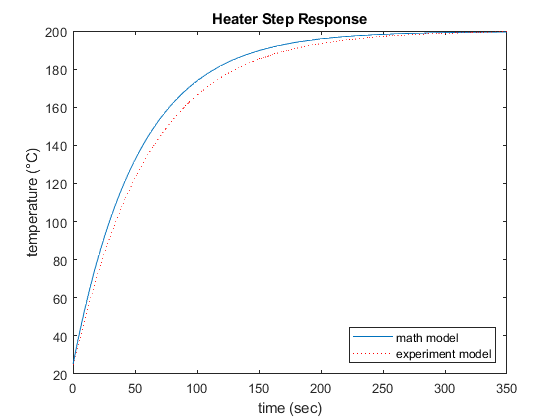

plot(tempGraph1.TIME,tempGraph1.Tov,'r:');
xlabel('time (sec)');
ylabel('temperature (°C)');
title('Heater Step Response');
legend('math model','experiment model','Location','southeast');

### Results

From the comparison between the data from the mathematical model and from the experiment model, it is seen that there is a slight difference between the response from the mathematical model and the response from the experiment model, however, since both models reach the steady-state almost at the same time, this provides a good starting point to design the controller.